flights = importFlightsData("flightsJan.csv")

flights = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________

groupsummary(flights, "ORIGIN" )

ans = ans(~ismissing(ans.GroupCount),:);
ans = sortrows(ans,'GroupCount','descend')

ans = 312×2 table
    ORIGIN    GroupCount
    ______    __________

     ABE          164   
     ABI          239   
     ABQ         1574   
     ABR           62   
     ABY           81   
     ACT          147   
     ACV          150   
     ACY          341   
     ADK            9   
     ADQ           30   
     AEX          282   
     AGS          200   
     ALB          569   
     ALO           58   
     AMA          525   
     ANC         1184   


groupsummary(flights, "ORIGIN" , 'mean', 'DISTANCE')

ans = ans(~ismissing(ans.mean_DISTANCE),:);
ans = sortrows(ans,'mean_DISTANCE')

ans = 312×3 table
    ORIGIN    GroupCount    mean_DISTANCE
    ______    __________    _____________

     ABE          164          568.52    
     ABI          239             158    
     ABQ         1574          687.13    
     ABR           62             257    
     ABY           81             145    
     ACT          147              89    
     ACV          150             250    
     ACY          341          887.82    
     ADK            9            1192    
     ADQ           30             253    
     AEX          282          341.15    
     AGS          200             143    
     ALB          569          755.76    
     ALO           58             234    
     AMA          525          377.41    
     ANC         1184          1276.5    


flights

flights = flights(flights.CANCELLED == 1,:)

flights = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________

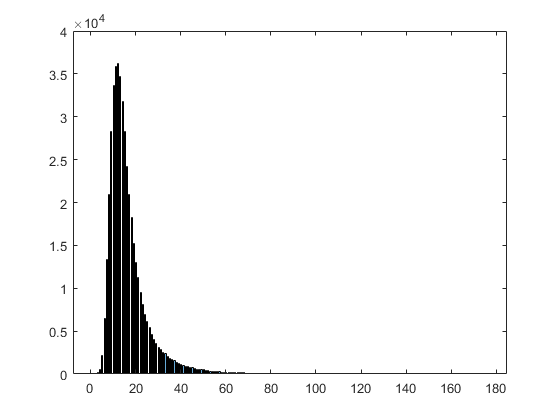

histogram(flights.TAXI_OUT)